# Module 1 - Uncertainty and Entropy I

Author: J. Lizier, 2017-

# 1. Coding Shannon information content

During our Introduction to Information Theory block, we will alter several Matlab functions in order to compute information-theoretic  quantities.

Our first activity with these templates is to implement the Shannon information content:


$$h\left(x\right)=\log_2{\left( \frac{1}{p(x)} \right)}=-\log_2 {p(x)}$$


1. Edit the function `infocontent(p)` in the file [infocontent.m](matlab:open('./infocontent.m')) to return the Shannon information content for an outcome $$x$$ with probability $$p(x)$$. Make sure that you use the function `log2()` rather than `log()` to get your answers in bits rather than nats:

- the value that we want is `-log2(p)`

- and we can assign this to be returned from the function by by assigning it to the return variable: r`esult=-log2(p); `and

2. To evaluate a function in Matlab, we type it's name with an appropriate argument supplied in brackets. For example, to evaluate the Shannon information content with our function for an outcome with had probability 0.2, you would call: `infocontent(0.2).` Leaving off a trailing `;` means that Matlab will print the answer to the screen (otherwise including a trailing `;` suppresses the output). You can enter commands like `infocontent(0.2)` either in the command window after the `>>` prompt and press return, or in the code cell below and evaluate it.

Compute the following using your function:

- *h(*heads*)* for a fair coin?

- *h(1)* for a 6-sided die? *h(*not 1*)* for a 6-sided die?

- *h(1)* for a 20-sided die? *h(*not 1*)* for a 20-sided die?

% h(heads) for a fair coin?
infocontent(0.5)

ans = 1

% h(1) for a 6-sided die?
infocontent(1/6)

ans = 2.5850

% h(not 1) for a 6-sided die?
infocontent(5/6)

ans = 0.2630

% h(1) for a 20-sided die?
infocontent(1/20)

ans = 4.3219

% h(not 1) for a 20-sided die?
infocontent(19/20)

ans = 0.0740

`3. `Reproduce the plot below of *h(x)* versus *p(x)* using the Matlab `plot()` function.

Hints:

- Input `p` to `infocontent(p)` as a vector across the range `p=0.01:0.01:1`

- Call the `plot(x, y)` function with `p` and `infocontent(p)`

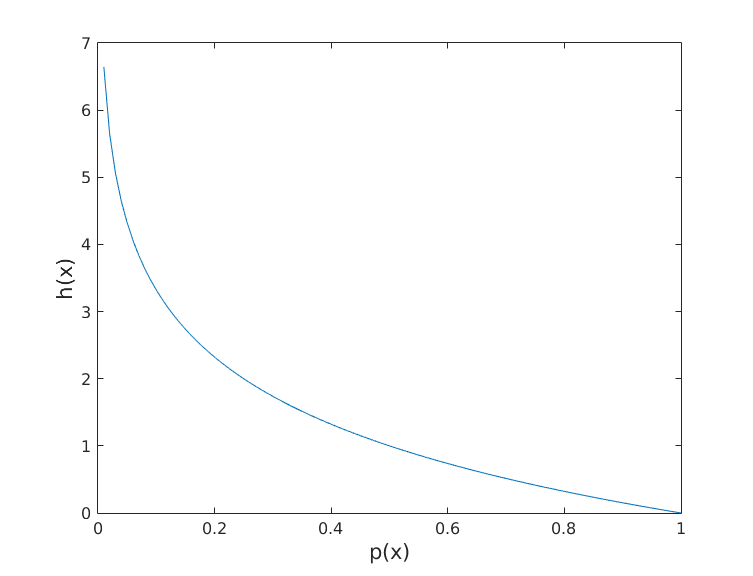

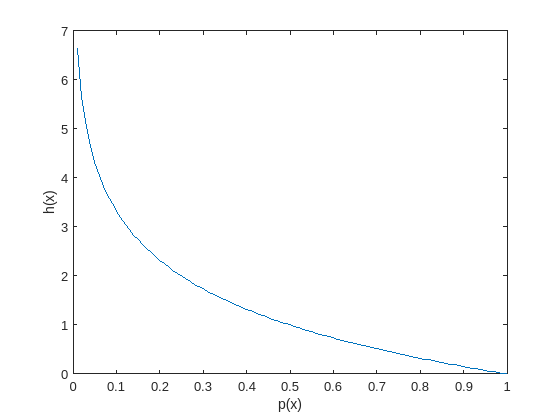

% Define the array for p
p = 0.01:0.01:1;
% Compute the infocontent() of the array p
% Make the plot and don't forget to label axes
plot(p, infocontent(p));
xlabel('p(x)');
ylabel('h(x)');

4. Have a look at the characters that we could play Guess Who? with on the [Kooky characters sheet](https://web.archive.org/web/20170215034006/http://www.hasbro.com/upload/guesswho/GWc_Kooky-en_GB.pdf). Assuming that your partner selects one of these characters at random, compute the probability and then the Shannon information content of their character: 

- being Jason?

- having one eye?

- having more than one eye?

% h(Jason)?
infocontent(1/24)

ans = 4.5850

% h(one eye)?
infocontent(5/24)

ans = 2.2630

% h(more than one eye)?
infocontent(19/24)

ans = 0.3370

5. Based on those answers, reflect on the following:

- Would a good first question be "*does your character have one eye?*" ? Why / why not?

- Would a good first question be "*are you Jason?*" ? Why / why not?

# 2. Coding Shannon entropy

In this exercise we continue to generate Matlab code to measure the Shannon entropy for a distribution $$p(x)$$:


$$H(X)=-\sum_xp\left(x\right)\log_2p\left(x\right)$$


Your task is to edit the function `entropy(p)` in the file [entropy.m](matlab:open('./entropy.m')) to return the Shannon entropy for the given distribution $$p(x)$$ over outcomes $$x$$ of $$X$$.

Note the input argument to the function is a vector `p`, representing the probability mass for each outcome of $$x$$. That is, `p` is a vector with the *n*th entry in the vector giving the probability for the *n*th value that $$x$$ may take. The sum of the items in the vector `p` must be 1.

For example, for a binary $$x$$ we could have `p = [0.25, 0.75]` where $p(x=0) = 0.25$ and $p(x=1) = 0.75$.

- If we knew $$x$$ was a binary variable, and we only took one argument, $p = p(x=1)$, how could you write one line of code to compute $H(X)$ from $p$? (*Hint*: what would $log_2 p(x=1)$ be as a function of $p$? What would $log_2 p(x=0)$ be as a function of $p$? Can you combine these to give $H(X)$?)

Let's assume that we don't know how many values $$x$$ could take, and write the code for an arbitrary length vector `p`.

1. Can you think of two ways to write the code to sum up the contribution for each item $$p(x)$$ in the vector $$x$$, being: 

- a for loop over the items of `p`, or

- the sum of a vector multiplication or dot product in Matlab?

**Implement one of these** in `entropy(p)` in the file [entropy.m](matlab:open('./entropy.m')). (If you know Matlab, you will know that the vector dot multiplication will be faster)

2. Think of possible error conditions here, and how you can handle these in your code.

3. Write down the answer you expect, and test that your code gives answers you expect for: 

- `entropy([0.5, 0.5])`

- `entropy([0.25, 0.25, 0.25, 0.25])`

- `entropy([1, 0])`

% entropy([0.5, 0.5]) ?
entropy([0.5, 0.5])

ans = 1

% entropy([0.25, 0.25, 0.25, 0.25]) ?
entropy([0.25, 0.25, 0.25, 0.25])

ans = 2

% entropy([1, 0]) ?
entropy([1, 0])

ans = 0

4. *Challenge*: Plot $H(X)$ as a function of $p(x=1)$ for binary $$X$$. (See the plot we expect on the figure below). This will involve a loop over values of $p = p(x=1)$ to call the `entropy(p)` function with a vector corresponding to each $\{ p(x=1), p(x=0) \}$ pair.

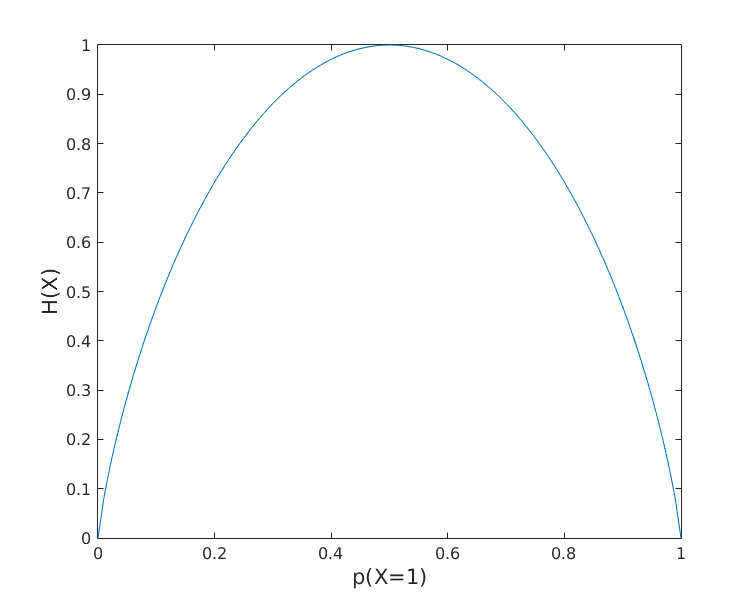

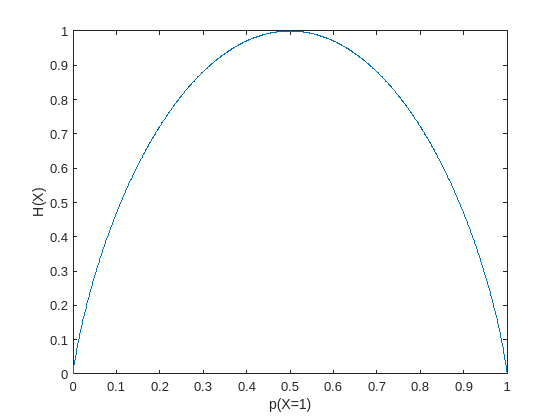

% Add your code to plot H(X) vs p(x=1) below, and don't forget to label axes
p=0:0.001:1;
H=zeros(1,length(p));

for ix = 1:length(p)
    H(ix) = entropy([p(ix), 1 - p(ix)]);
end

plot(p, H);
xlabel('p(X=1)');
ylabel('H(X)');

5. Coming back to the characters that we could play *Guess Who?* with on the [Kooky characters sheet](https://web.archive.org/web/20170215034006/http://www.hasbro.com/upload/guesswho/GWc_Kooky-en_GB.pdf), validate that (using your `entropy` function):

- $H(who)=4.585$ bits  (entropy of the character's identity)

- $H(one\ eye?)=0.738$ bits  (entropy of whether the character has one eye or more than one eye)

- $H(Jason)=0.2499$ bits  (entropy of whether the character is Jason or not)

% Add your code here to validate the entropies as above:
entropy(ones(1,24)*1/24)

ans = 4.5850

entropy([5/24, 19/24])

ans = 0.7383

entropy([1/24, 23/24])

ans = 0.2499

6. Based on those answers and in comparison to your responses on the earlier exercise, reflect on the following: 

- Would a good first question be "*does your character have one eye?*" ? Why / why not?

- Would a good first question be "*are you Jason?*" ? Why / why not?

- What is the best question to ask first that you can think of, and why? (as an optional tangent, you could watch [a video](https://youtu.be/FRlbNOno5VA) which goes into some detail about what the best questions might be -- again, think about the information-theoretic view on what is being said there)